# Cleaning Workspace

clear;
close all;
clc;

# Initialization Parameters

## Ploting Parameters

linewidth  = 2;
fontname   = 'Times New Roman';
fontsize   = 20;
markersize = 10;

colors = [0.0000 0.0000 0.0000;
          0.0000 0.4470 0.7410;
          0.8500 0.3250 0.0980;
          0.9290 0.6940 0.1250;
          0.4940 0.1840 0.5560;
          0.4660 0.6740 0.1880;
          0.3010 0.7450 0.9330;
          0.6350 0.0780 0.1840];

# Communication System

## Data Transmission Parameters

Parameters related to the data transmission, e.g., number of bits, constellation size, number of subcarriers, and number of transmitted blocks.

SNR   = 0:5:50;                        % Signal-to-noise ratio in dB
N_SNR = length(SNR);                   % Length of SNR

B     = 5;                             % Number of bits in a symbol
Q     = 2^B;                           % Constellation size

L     = 15;                             % Channel's length in samples

M     = 64;                            % Number of subcarriers
K     = L;                             %
N     = M+K;                           %

N_BLK = 5000;                          % The number of transmitted data blocks

N_EQ  = 2;

N_FFT  = 1024;

freq_N = 2*pi*linspace(-0.5,0.5,N_FFT);
freq_M = 2*pi*linspace(-0.5,0.5,M);

## Channel Encoder Parameters

R = 0.5;

constraint_length = 7;
tblen = 5*constraint_length;

g0 = 133;
g1 = 165;

state = randi([1 1e6],1,1);

trellis = poly2trellis(constraint_length,[g0 g1]);

BER = zeros(N_SNR,N_EQ,4);

A_cp = [zeros(K,M-K) eye(K); eye(M)];
R_cp = [zeros(M,K) eye(M)];

A_zp = [eye(M); zeros(K,M)];
R_zp = [eye(M) [eye(K); zeros(M-K,K)]];

x  = zeros(N*N_BLK/R,4);
Px = zeros(4,1);

y_p              = zeros(N,N_BLK/R,4,N_SNR);
m_mod_hat        = zeros(M,N_BLK/R,N_EQ,4,N_SNR);
m_hat            = zeros(B*M*N_BLK/R,N_EQ,4,N_SNR);
code_hat_deitrlv = zeros(B*M*N_BLK/R,N_EQ,4,N_SNR);
m_bit_hat        = zeros(B*M*N_BLK,N_EQ,4,N_SNR);

## Transmitter

m_bit     = randi([0 1],B*M*N_BLK,1);

code      = convenc(m_bit,trellis);
code_itlv = randintrlv(code,state);

m_mod     = qammod(code_itlv,Q,'InputType','bit'); % Q-QAM modulation
m_mod     = reshape(m_mod,M,N_BLK/R);

s = m_mod;
s = A_cp*s;

x(:,1) = reshape(s,[],1);
Px(1)  = norm(x(:,1))^2/length(x(:,1));                   % Average transmission power

s = m_mod;
s = A_zp*s;

x(:,2) = reshape(s,[],1);
Px(2)  = norm(x(:,2))^2/length(x(:,2));                   % Average transmission power

s = sqrt(M)*ifft(m_mod,M);
s = A_cp*s;

x(:,3) = reshape(s,[],1);
Px(3)  = norm(x(:,3))^2/length(x(:,3));                   % Average transmission power

s = sqrt(M)*ifft(m_mod,M);
s = A_zp*s;

x(:,4) = reshape(s,[],1);
Px(4)  = norm(x(:,4))^2/length(x(:,4));                   % Average transmission power

## Channel

h = randn(L+1,1) +1i*rand(L+1,1);
h = h/norm(h);

h_freq = fft(h,N_FFT);
lambda = fft(h,M);

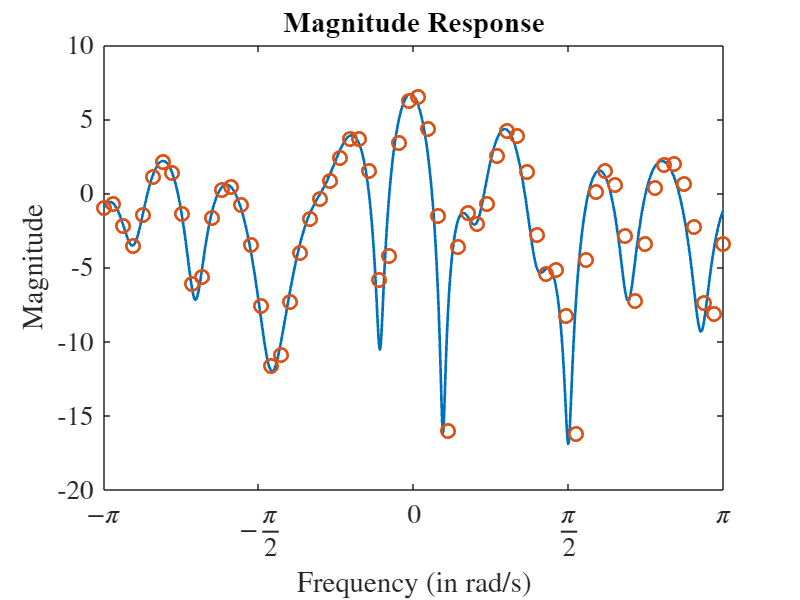

figure;

set(gcf,'position',[0 0 800 600])

plot(freq_N,fftshift(20*log10(abs(h_freq))),'linewidth',linewidth,'markersize',markersize);
hold on;
plot(freq_M,fftshift(20*log10(abs(lambda))),'o','linewidth',linewidth,'markersize',markersize);

title('Magnitude Response','fontname',fontname,'fontsize',fontsize);
xlabel('Frequency (in rad/s)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('Magnitude','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xticks([-pi -pi/2 0 pi/2 pi]);

xlim([-pi,pi]);

set(gca,'ticklabelinterpreter','latex', ...
    'xticklabel',{'$-\pi$','$-\frac{\pi}{2}$','$0$','$\frac{\pi}{2}$','$\pi$'}, ...
    'fontname',fontname,'fontsize',fontsize);

z = fftfilt(h,x);                                              % Filter signal by channel

## Receiver

for snr_ind = 1:N_SNR 
    v  = randn(N*N_BLK/R,1) + 1i*randn(N*N_BLK/R,1);           % AWGN noise
    Pv = norm(v)^2/length(v);                                  % Average noise power
    
    v_1 = sqrt(((Px(1)/Pv))*(10^(-SNR(snr_ind)/10)))*v;       % True AWGN noise
    v_2 = sqrt(((Px(2)/Pv))*(10^(-SNR(snr_ind)/10)))*v;       % True AWGN noise
    v_3 = sqrt(((Px(3)/Pv))*(10^(-SNR(snr_ind)/10)))*v;       % True AWGN noise
    v_4 = sqrt(((Px(4)/Pv))*(10^(-SNR(snr_ind)/10)))*v;       % True AWGN noise

    y = z + [v_1 v_2 v_3 v_4];                                 % Received signal
    
    y_p(:,:,1,snr_ind) = reshape(y(:,1),N,N_BLK/R);           % Serial to parallel conversion
    y_p(:,:,2,snr_ind) = reshape(y(:,2),N,N_BLK/R);
    y_p(:,:,3,snr_ind) = reshape(y(:,3),N,N_BLK/R);
    y_p(:,:,4,snr_ind) = reshape(y(:,4),N,N_BLK/R);

    Equalizer_zf = diag(1./lambda);
    Equalizer_mmse = diag(conj(lambda)./(abs(lambda).^2 + 10^(-SNR(snr_ind)/10)));

    m_mod_hat(:,:,1,1,snr_ind) = ifft(Equalizer_zf*fft(R_cp*y_p(:,:,1,snr_ind)));
    m_mod_hat(:,:,2,1,snr_ind) = ifft(Equalizer_mmse*fft(R_cp*y_p(:,:,1,snr_ind)));

    m_hat(:,1,1,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,1,snr_ind),[],1),Q,'OutputType','bit');
    m_hat(:,2,1,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,1,snr_ind),[],1),Q,'OutputType','bit');

    code_hat_deitrlv(:,1,1,snr_ind) = randdeintrlv(m_hat(:,1,1,snr_ind),state);
    code_hat_deitrlv(:,2,1,snr_ind) = randdeintrlv(m_hat(:,2,1,snr_ind),state);

    m_bit_hat(:,1,1,snr_ind) = vitdec(code_hat_deitrlv(:,1,1,snr_ind),trellis,tblen,'trunc','hard');
    m_bit_hat(:,2,1,snr_ind) = vitdec(code_hat_deitrlv(:,2,1,snr_ind),trellis,tblen,'trunc','hard');

    [~,BER(snr_ind,1,1)] = biterr(m_bit_hat(:,1,1,snr_ind),m_bit);
    [~,BER(snr_ind,2,1)] = biterr(m_bit_hat(:,2,1,snr_ind),m_bit);

    m_mod_hat(:,:,1,2,snr_ind) = ifft(Equalizer_zf*fft(R_zp*y_p(:,:,2,snr_ind)));
    m_mod_hat(:,:,2,2,snr_ind) = ifft(Equalizer_mmse*fft(R_zp*y_p(:,:,2,snr_ind)));

    m_hat(:,1,2,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,2,snr_ind),[],1),Q,'OutputType','bit');
    m_hat(:,2,2,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,2,snr_ind),[],1),Q,'OutputType','bit');

    code_hat_deitrlv(:,1,2,snr_ind) = randdeintrlv(m_hat(:,1,2,snr_ind),state);
    code_hat_deitrlv(:,2,2,snr_ind) = randdeintrlv(m_hat(:,2,2,snr_ind),state);

    m_bit_hat(:,1,2,snr_ind) = vitdec(code_hat_deitrlv(:,1,2,snr_ind),trellis,tblen,'trunc','hard');
    m_bit_hat(:,2,2,snr_ind) = vitdec(code_hat_deitrlv(:,2,2,snr_ind),trellis,tblen,'trunc','hard');

    [~,BER(snr_ind,1,2)] = biterr(m_bit_hat(:,1,2,snr_ind),m_bit);
    [~,BER(snr_ind,2,2)] = biterr(m_bit_hat(:,2,2,snr_ind),m_bit);

    m_mod_hat(:,:,1,3,snr_ind) = Equalizer_zf*fft(R_cp*y_p(:,:,3,snr_ind))/sqrt(M);
    m_mod_hat(:,:,2,3,snr_ind) = Equalizer_mmse*fft(R_cp*y_p(:,:,3,snr_ind))/sqrt(M);

    m_hat(:,1,3,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,3,snr_ind),[],1),Q,'OutputType','bit');
    m_hat(:,2,3,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,3,snr_ind),[],1),Q,'OutputType','bit');

    code_hat_deitrlv(:,1,3,snr_ind) = randdeintrlv(m_hat(:,1,3,snr_ind),state);
    code_hat_deitrlv(:,2,3,snr_ind) = randdeintrlv(m_hat(:,2,3,snr_ind),state);

    m_bit_hat(:,1,3,snr_ind) = vitdec(code_hat_deitrlv(:,1,3,snr_ind),trellis,tblen,'trunc','hard');
    m_bit_hat(:,2,3,snr_ind) = vitdec(code_hat_deitrlv(:,2,3,snr_ind),trellis,tblen,'trunc','hard');

    [~,BER(snr_ind,1,3)] = biterr(m_bit_hat(:,1,3,snr_ind),m_bit);
    [~,BER(snr_ind,2,3)] = biterr(m_bit_hat(:,2,3,snr_ind),m_bit);

    m_mod_hat(:,:,1,4,snr_ind) = Equalizer_zf*fft(R_zp*y_p(:,:,4,snr_ind))/sqrt(M);
    m_mod_hat(:,:,2,4,snr_ind) = Equalizer_mmse*fft(R_zp*y_p(:,:,4,snr_ind))/sqrt(M);

    m_hat(:,1,4,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,1,4,snr_ind),[],1),Q,'OutputType','bit');
    m_hat(:,2,4,snr_ind) = qamdemod(reshape(m_mod_hat(:,:,2,4,snr_ind),[],1),Q,'OutputType','bit');

    code_hat_deitrlv(:,1,4,snr_ind) = randdeintrlv(m_hat(:,1,4,snr_ind),state);
    code_hat_deitrlv(:,2,4,snr_ind) = randdeintrlv(m_hat(:,2,4,snr_ind),state);

    m_bit_hat(:,1,4,snr_ind) = vitdec(code_hat_deitrlv(:,1,4,snr_ind),trellis,tblen,'trunc','hard');
    m_bit_hat(:,2,4,snr_ind) = vitdec(code_hat_deitrlv(:,2,4,snr_ind),trellis,tblen,'trunc','hard');

    [~,BER(snr_ind,1,4)] = biterr(m_bit_hat(:,1,4,snr_ind),m_bit);
    [~,BER(snr_ind,2,4)] = biterr(m_bit_hat(:,2,4,snr_ind),m_bit);
end


# Ploting Results

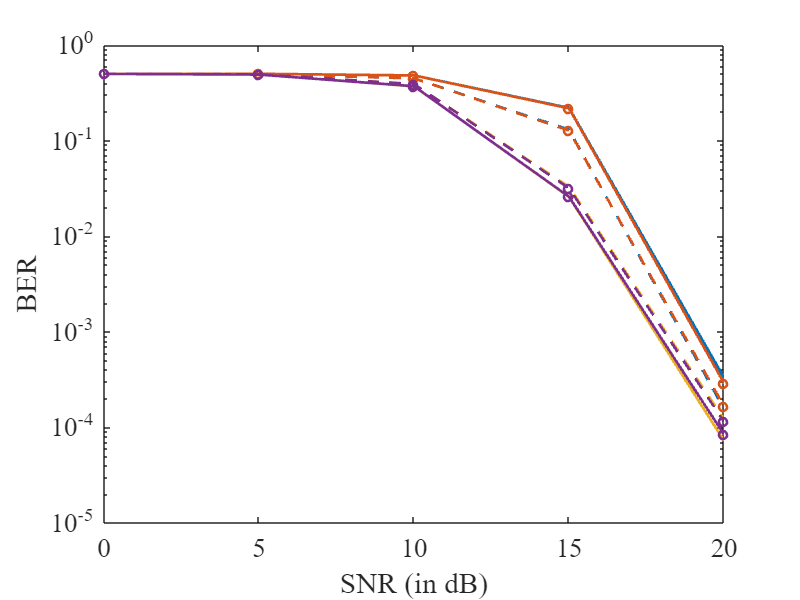

figure;

set(gcf,'position',[0 0 800 600])

semilogy(SNR,BER(:,1,1),'-'  ,'color',colors(2,:),'linewidth',linewidth);
hold on;
semilogy(SNR,BER(:,2,1),'--' ,'color',colors(2,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,2),'o-' ,'color',colors(3,:),'linewidth',linewidth);
semilogy(SNR,BER(:,2,2),'o--','color',colors(3,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,3),'-'  ,'color',colors(4,:),'linewidth',linewidth);
semilogy(SNR,BER(:,2,3),'--' ,'color',colors(4,:),'linewidth',linewidth);
semilogy(SNR,BER(:,1,4),'o-' ,'color',colors(5,:),'linewidth',linewidth);
semilogy(SNR,BER(:,2,4),'o--','color',colors(5,:),'linewidth',linewidth);

% title('$N = 32$','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

xlabel('SNR (in dB)','fontname',fontname,'fontsize',fontsize);
ylabel('BER','fontname',fontname,'fontsize',fontsize);

% legend({'AWGN','Multipath','$L = 10$','$L = 20$','$L = 30$'},'fontname',fontname,'fontsize',fontsize,'interpreter','latex','location','southwest')
% legend box off

% xlim([-5 10]);

set(gca,'fontname',fontname,'fontsize',fontsize);